# Problem 1:

## Tarun Kamath

- The initial position for all the particles is at 0.

- Since the X matrix has 1001 columns, the last t point is at t = 1000

- Below is the plot of particle 14

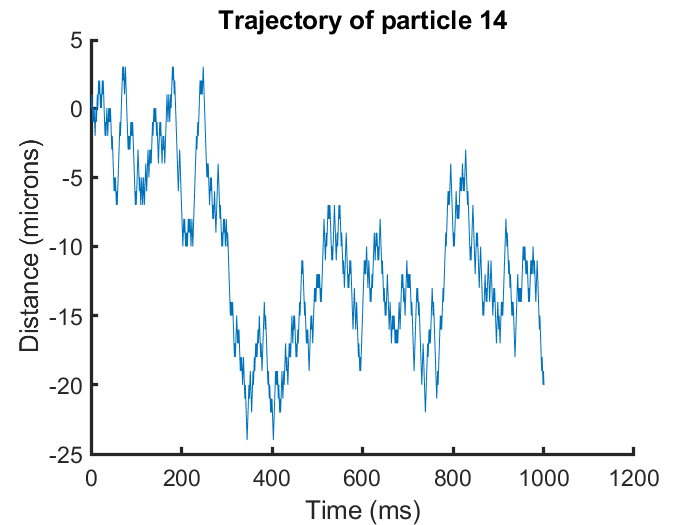

%% Load a file
load('randomwalk.mat');

%% Plot trajectory of particle #14 (1-3)
fig1 = figure(1);
plot(X(14,:)) 

title('Trajectory of particle 14');
xlabel('Time (ms)');
ylabel('Distance (microns)');
box off
ax = gca;
ax.FontSize = 14;
ax.LineWidth=2;

4. Below is all the trajectories of all the particles over time

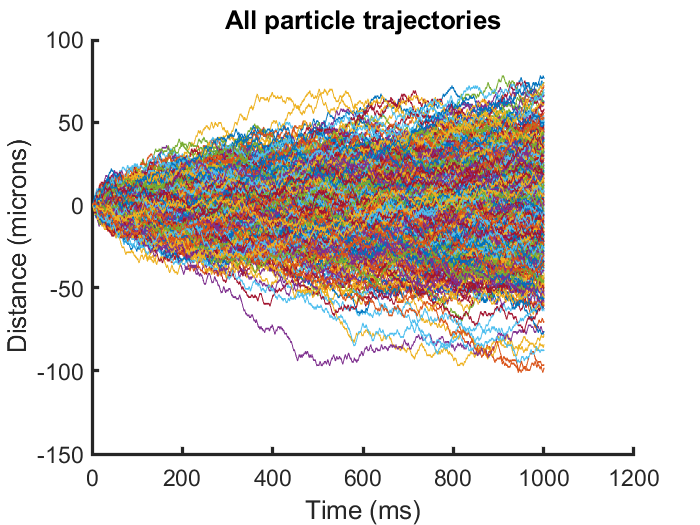

fig2 = figure(2);
for i = 1:500
    plot(X(i,:))  
    hold on
end

title('All particle trajectories');
xlabel('Time (ms)');
ylabel('Distance (microns)');
box off
ax = gca;
ax.FontSize = 14;
ax.LineWidth=2;

It seems that all the particles just follow random trajectories, but that the trajectories are relatively well distributed around the original starting point of 0 di5.stance. Each particle seems to follow a different trajectory since they have different ways to move at each time step.

5. Below is the mean displacement of all the particles

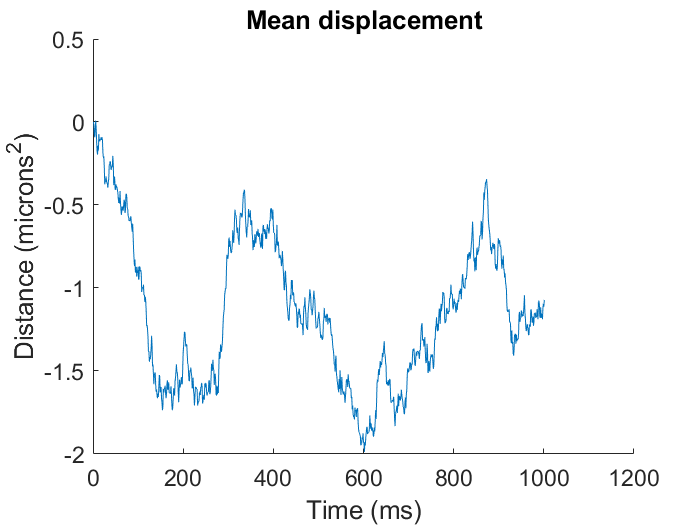

fig3 = figure(3);
meandisplacement = [];

M = mean(X);
plot([1:1001],M)

title('Mean displacement');
xlabel('Time (ms)');
ylabel('Distance (microns^2)');
box off
ax = gca;
ax.FontSize = 14;

It seems that in general the particles are moving in the negative direction over time.

6. Mean square displacement is plotted below

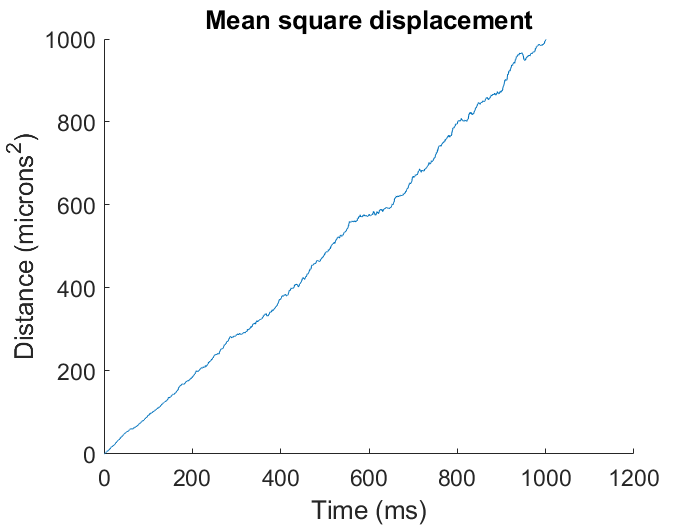

fig4 = figure(4);
squaredisplacement = X.^2;

meansquaredisplacement = mean(squaredisplacement);
plot([1:1001],meansquaredisplacement)

title('Mean square displacement');
xlabel('Time (ms)');
ylabel('Distance (microns^2)');
box off
ax = gca;
ax.FontSize = 14;

There is a general linear increase in the mean square displacement over time.

7.  We know that the variance of the mean square displacement will increase by a given factor, $\delta^2$. Thus we can say that


$$\begin{array}{l}
D=\frac{\delta^2 }{2∗\tau }\\
=\frac{\text{slope}}{2∗1}=\frac{1}{2}=0\ldotp 5\text{ }\frac{{\mathrm{microns}}^2 }{\mathrm{ms}}
\end{array}$$
    

# **Problem 2: Equivalent Circuit Model**

- The circuit is shown below:

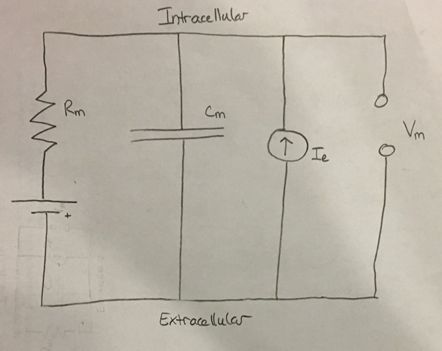

2. So the membrance conductance is simply


$$G_M =\text{ }g_m \ast SA$$


Where the SA represents the surface area of the neuron

Since the neuron is modeled as a sphere with radius 0.06 mm, we say


$$\begin{array}{l}
SA=4\ast \pi \ast r^2 =\text{ }\left(4\ast \pi \ast \text{ }\left({\ldotp 06}^2 \right)\right)=\ldotp 045\text{ }{mm}^2 \\
G_M =1\text{ }\frac{\mu S}{{mm}^2 }\ast \ldotp 045{mm}^2 =\ldotp 045\text{ }\mu S
\end{array}$$


Similarly resistance is calculated as


$$R_m =\frac{1}{G_m }=\frac{1}{\ldotp 045\mu S}=22\ldotp 2\text{ }M\Omega$$
			 

    3. Conductance is calculated as


$$\begin{array}{l}
C_m =c_m \ast SA\\
=10\text{ }\frac{nF}{{mm}^2 }\ast \ldotp 045\text{ }{mm}^2 =\ldotp 45\text{ }nF
\end{array}$$


    4. The time constant is calculated as


$$\tau =R\ast C=22\ldotp 2\text{ }M\Omega \ast 0\ldotp 45\text{ }nF=10\text{ }ms$$


5. Refer to RCPassive.m for the code that generates the figure shown below

6. 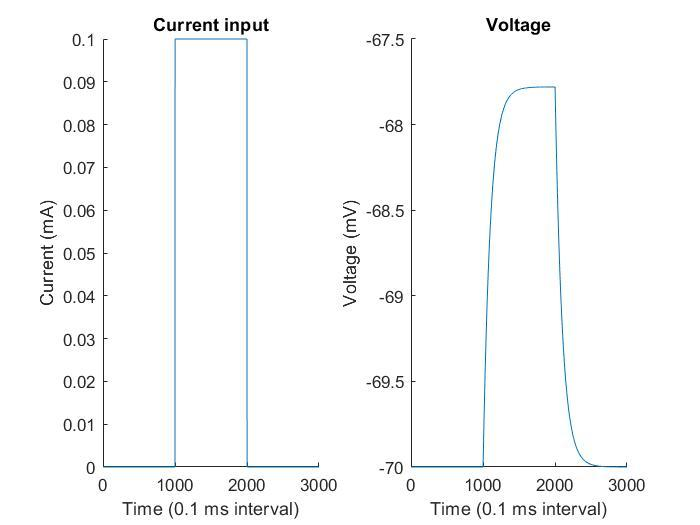

7. We know that the voltage difference between resting voltage and steady state voltage is -67.8 mV - -70 mV = 2.2 mV. To see how much of the difference in voltage is achieved by the time one time constant worth of time has passed, we do:


$$\left(1-\frac{1}{e}\right)∗\Delta V=0\ldotp 63∗2\ldotp 2\text{ }\mathrm{mV}=1\ldotp 38\text{ }\mathrm{mV}$$


Thus we want the time at which the voltage is -70 mV + 1.38 mV = -68.62 mV. We can see from the graph that this is at 1100, which is 100 * 0.1 ms = 10 ms after the current starts. Thus the time constant is **10 ms**.

8. This is the same as the value of time constant that we calculated in question 4.

9.       We can show this by plugging in Equation 2.2 into Equation 2.1:


$$\begin{array}{l}
V\left(t\right)+\tau_m \frac{dV}{dT}=V_{rest} +R_m I_e \\
=V_{rest} +R_m I_e +\text{ }\left(V_0 -V_{rest} -R_m I_e \right)e^{-\frac{\left(t-t_0 \right)}{\tau_m }} +\tau_m \ast \text{ }\left(V_0 -V_{rest\text{ }} -R_m I_e \right)\ast \frac{1}{-\tau_m }\ast e^{-\frac{\left(t-t_0 \right)}{\tau_m }} \\
=\text{ }V_{rest} +R_m I_e +\text{ }\left(V_0 -V_{rest} -R_m I_e \right)e^{-\frac{\left(t-t_0 \right)}{\tau_m }} -\left(V_0 -V_{rest\text{ }} -R_m I_e \right)e^{-\frac{\left(t-t_0 \right)}{\tau_m }} \\
=V_{rest\text{ }} +R_m I_e \text{ }
\end{array}$$


thus we can get to the solution that we expect given Equation 2.1

10. So at the initial time we have:


$$\begin{array}{l}
e^{-\frac{\left(t-t_0 \right)}{\tau_m }} =e^0 =1,thus\text{ }Equation\text{ }2\ldotp 2\text{ }becomes\\
V\left(t\right)=V_{rest} +I_e R_m +\text{ }\left(V_0 -V_{rest} -I_e R_m \right)\\
=V\text{ }\left(t\right)=V_0 
\end{array}$$


11. As t --> infinity, we have that the exponential will approach 0 (since the exponential is raised to the negative of time, thus it becomes exponentially :

smaller as time passes). Thus, by Equation 2.2, we have:


$$V\left(t\right)\to V_{rest} +I_e \ast R_m$$


12.     We will use Equation 2.2:


$$\begin{array}{l}
V\left(t\right)=V_{\mathrm{rest}} +R_m ∗I_e +\left(V_0 -V_{\mathrm{rest}} -R_m ∗I_e \right)∗e^{-\frac{\left(t-t_0 \right)}{\tau_m }} \\
=-60\text{ }\mathrm{mV}=-70\text{ }\mathrm{mV}+\left(22\ldotp 2\text{ }M\Omega \right)∗\left(0\ldotp 5\text{ }\mathrm{mA}\right)+\left(-70\text{ }\mathrm{mV}--70\text{ }\mathrm{mV}-22\ldotp 2\text{ }M\text{ }\Omega ∗0\ldotp 5\text{ }\mathrm{mA}\right)∗e^{-\frac{t}{22\ldotp 2\text{ }M\Omega ∗0\ldotp 45\text{ }\mathrm{nF}}} \\
=10\text{ }\mathrm{mV}=11\ldotp 1-11\ldotp 1∗e^{-\frac{t}{9\ldotp 9}} \\
=\frac{\left(1\ldotp 1\right)}{11\ldotp 1}=\ldotp 09=e^{-\frac{t}{9\ldotp 99}} \\
=t=23\ldotp 4\text{ }s
\end{array}$$
  

The steady state voltage is given below:


$$V_{\infty } =V_{\mathrm{rest}} +R_m ∗I_e =-70\text{ }\mathrm{mV}+22\ldotp 2\text{ }M\Omega ∗0\ldotp 5\text{ }\mathrm{mA}=-58\ldotp 9\text{ }\mathrm{mV}$$


13. Resistors in parallel add according to the following equation:


$$\frac{1}{R_{total} }=\frac{1}{R_1 }+\frac{1}{R_2 }+\frac{1}{R_3 }+\ldotp \ldotp \ldotp$$


Thus, let us say that the initial resistance, was 100 ohms. Then our additional resistance is another 100 ohms. Thus our new total resistance will be:


$$\begin{array}{l}
\frac{1}{R_{total} }=\frac{1}{100}+\frac{1}{100}=\frac{2}{100}\\
R_{total} =\frac{100}{2}=50\Omega \\
So\text{ }now\text{ }our\text{ }time\text{ }constant\text{ }is\\
\tau =R\ast C\text{ }\\
\text{ }
\end{array}$$


So, since the total resistance has decreased, from 100 ohms to 50 ohms, the time constant has also decreased, and become faster.

# Problem 3: Nernst Potential

- Refer to the NernstPotential.m code

- From the code,we find that the potential for K+ ions is 97.8 mV and for Ca2+ ions is -137.9 mV

# Problem 4: Ion fluxes and Nernst Potential

- So we first need the volume of the neuron


$$\begin{array}{l}
V=\frac{4}{3}\ast \pi \ast r^{3\text{ }} =\frac{4}{3}\ast \pi \ast {\left(\ldotp 06\text{ }mm\right)}^3 =9\ast {10}^{-10} L\\
186\text{ }mM\ast 9\ast {10}^{-10} \text{ }L\ast 1\text{ }\frac{mol}{1000\text{ }mmol}\ast 6\ldotp 02\ast {10}^{23} \frac{atoms}{mol}=1\ast {10}^{14\text{ }} ions
\end{array}$$


2. So we know from problem 3 what the steady state voltage is: 


$$\begin{array}{l}
V_{\infty } =V_{\text{rest}} +I_e ∗R_m \text{ }\\
=97\ldotp 8\text{ }\text{mV}
\end{array}$$


3. The net charge accumulated can be calculated as follows:


$$q=C\ast V=97\ldotp 9\text{ }mV\ast \ldotp 45\text{ }nF=4\ldotp 4\text{ }\ast \text{ }{10}^{-12} \text{ }Coulombs$$


4. We can say that the change in number of potassium ions is proportional to the change in charge, which is the net charge accumulated. Thus we say:


$$\Delta K^+ =\frac{q}{1\ldotp 6\ast {10}^{-19} \frac{C}{ion}}=\frac{\left(4\ldotp 4\ast {10}^{-12} \right)}{1\ldotp 6\ast {10}^{-19} }=27500000\text{ }ions$$


There is an outwards flow of potassium ions given the relatively high intracellular concentration.

5. Now that we know the change in number of potassium ions, it is relatively simple to calculate the change in concentration:


$$\Delta \left\lbrack K^+ \right\rbrack =27500000\text{ }ions\ast \frac{1}{6\ldotp 02\ast {10}^{23\text{ }} \frac{ions}{mol}}\ast \frac{1}{9\ast {10}^{-10\text{ }} L}=5\ldotp 1\ast {10}^{-8\text{ }} M$$


This does not change the physiological properties of the cell itself since this is simply changing the ion concentration in the neuron, not the channels or the neuron itself.